LPV-RTAC class3

clear;
w_max = 0.6817;
w_min = 0;
alpha1 = 0;
alpha2 = alpha1;
beta1 = 0.6817;
beta2 = 0.3183;
eta1 = -0.6817;
nu1 = 0.6817;
eta2 = -0.6817;
nu2 = 0.6817;
eps_p = 0.2;
A0 = [0,1,0,0;
    -1,0,eps_p/pi,0;
    0,0,0,1;
    0,0,0,0];
B0 = [0,0,0,1]';
A1 = [0,0,0,0;
    0,0,eps_p,0;
    0,0,0,0;
    0,0,0,0];
B1 = zeros(4,1);
A2 = -A1;
B2 = B1;

第一类控制器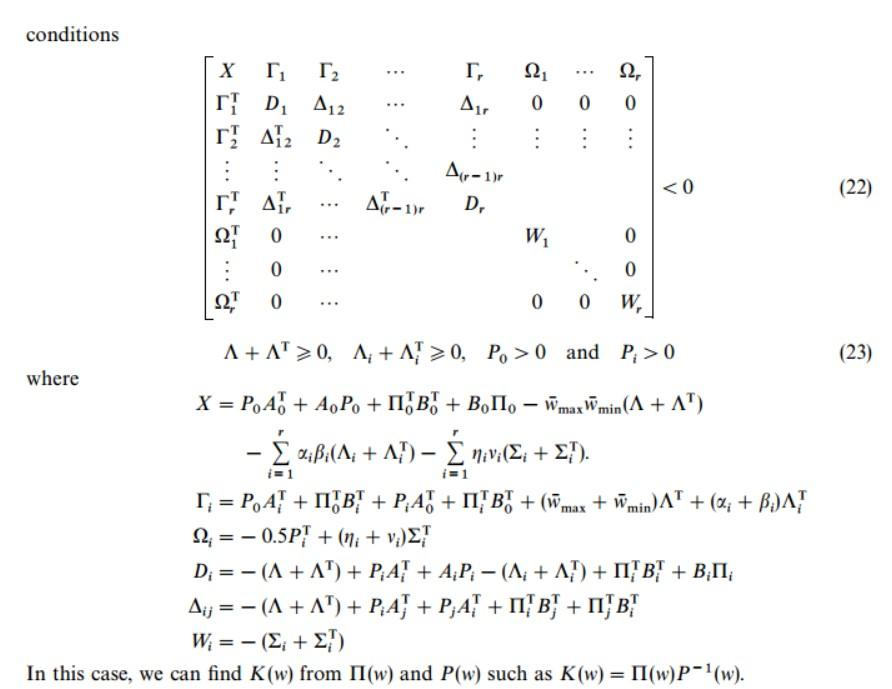

pvar z1 z2 z3 z4;
z=[z1;z2;z3;z4];
prog = sosprogram(z);
% [prog,P] = sospolymatrixvar(prog,monomials(z,0),[4,4],'symmetric');
[prog,P0] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
[prog,P1] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
[prog,P2] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
[prog,Sigma1] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
[prog,Sigma2] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
[prog,Pi0] = sospolymatrixvar(prog,monomials(z,0),[1,4]);
[prog,Pi1] = sospolymatrixvar(prog,monomials(z,0),[1,4]);
[prog,Pi2] = sospolymatrixvar(prog,monomials(z,0),[1,4]);
[prog,Lamda] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
[prog,Lamda1] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
[prog,Lamda2] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
X = P0*A0'+A0*P0+Pi0'*B0'+B0*Pi0-w_max*w_min*(Lamda+Lamda')...
    -alpha1*beta1*(Lamda1+Lamda1')-alpha2*beta2*(Lamda2+Lamda2')...
    -eta1*nu1*(Sigma1+Sigma1')-eta2*nu2*(Sigma2+Sigma2');
Tao1 = P0*A1'+Pi0'*B1'+P1*A0'+Pi1'*B0'+(w_max+w_min)*Lamda'+(alpha1+beta1)*Lamda1';
Tao2 = P0*A2'+Pi0'*B2'+P2*A0'+Pi2'*B0'+(w_max+w_min)*Lamda'+(alpha2+beta2)*Lamda2';
Omega1 = -0.5*P1'+(eta1+nu1)*Sigma1';
Omega2 = -0.5*P2'+(eta2+nu2)*Sigma2';
D1 = -(Lamda+Lamda')+P1*A1'+A1*P1-(Lamda1+Lamda1')+Pi1'*B1'+B1*Pi1;
D2 = -(Lamda+Lamda')+P2*A2'+A2*P2-(Lamda2+Lamda2')+Pi2'*B2'+B2*Pi2;
Delta12 = -(Lamda+Lamda')+P1*A2'+P2*A1'+Pi1'*B2'+Pi2'*B1';
W1 = -(Sigma1+Sigma1');
W2 = -(Sigma2+Sigma2');
% F = [X,Tao1,Tao2,Omega1,Omega2;
%     Tao1',D1,Delta12,zeros(4,4),zeros(4,4);
%     Tao2',Delta12',D2,zeros(4,4),zeros(4,4);
%     Omega1',zeros(4,4),zeros(4,4),W1,zeros(4,4);
%     Omega2',zeros(4,4),zeros(4,4),zeros(4,4),W2];
% %添加约束
% % prog = sosmatrixineq(prog, eps1, 'quadraticMineq');
% prog = sosmatrixineq(prog, -F-(1e-8), 'quadraticMineq');
% prog = sosmatrixineq(prog, (Lamda+Lamda'), 'quadraticMineq');
% prog = sosmatrixineq(prog, (Lamda1+Lamda1'), 'quadraticMineq');
% prog = sosmatrixineq(prog, (Lamda2+Lamda2'), 'quadraticMineq');
% prog = sosmatrixineq(prog, (Sigma1+Sigma1'), 'quadraticMineq');
% prog = sosmatrixineq(prog, (Sigma2+Sigma2'), 'quadraticMineq');
% prog = sosmatrixineq(prog, P0-(1e-5), 'quadraticMineq');
% prog = sosmatrixineq(prog, P1-(1e-5), 'quadraticMineq');
% prog = sosmatrixineq(prog, P2-(1e-5), 'quadraticMineq');
% %求解
% prog = sossolve(prog);
% %返回值
% P0 = double(sosgetsol(prog,P0));
% P1 = double(sosgetsol(prog,P1));
% P2 = double(sosgetsol(prog,P2));
% Pi0 = double(sosgetsol(prog,Pi0));
% Pi1 = double(sosgetsol(prog,Pi1));
% Pi2 = double(sosgetsol(prog,Pi2));
% P0,P1,P2,Pi0,Pi1,Pi2
%状态反馈增益阵

保性能控制器

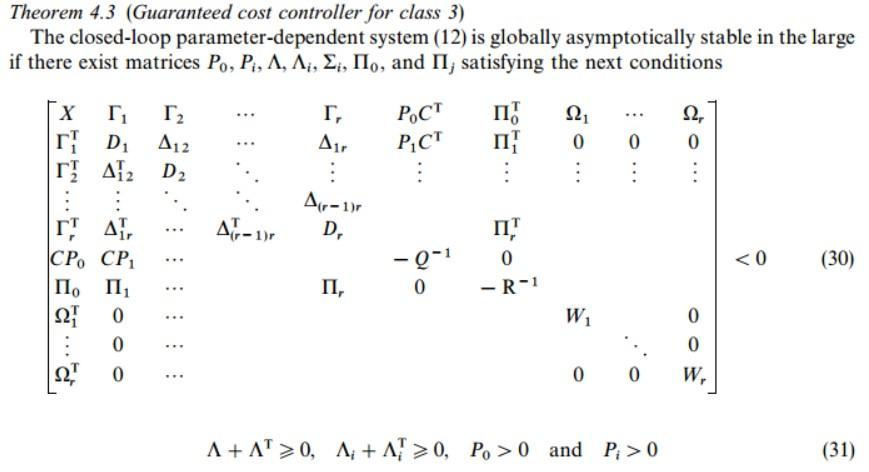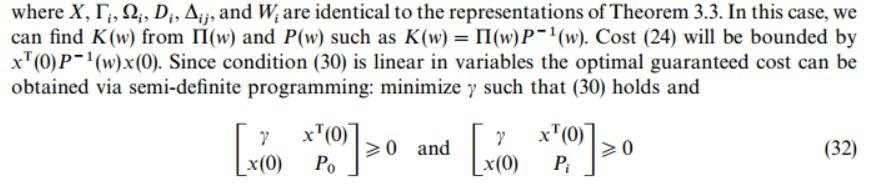

[prog,gamma] = sospolymatrixvar(prog,monomials(z,0),[1,1]);
C = [1,0,1,0];
Q = 1;
R = 1;
F1 = [X,   Tao1,        Tao2,   P0*C',           Pi0',       Omega1,         Omega2;
    Tao1',  D1,        Delta12, P1*C',           Pi1',     zeros(4,4),       zeros(4,4);
    Tao2', Delta12',       D2,  P2*C',           Pi2',     zeros(4,4),       zeros(4,4);
     C*P0,  C*P1,        C*P2,    -Q,             0,       zeros(1,4),       zeros(1,4);
     Pi0,   Pi1,         Pi2,       0,           -R,       zeros(1,4),       zeros(1,4);
     Omega1',zeros(4,4),zeros(4,4),zeros(4,1),zeros(4,1),     W1    ,        zeros(4,4);
     Omega2',zeros(4,4),zeros(4,4),zeros(4,1),zeros(4,1),  zeros(4,4),           W2];
x0 = [0,0,0,0]';
M0 = [gamma,x0';
    x0,P0];
M1 = [gamma,x0';
    x0,P1];
M2 = [gamma,x0';
    x0,P2];

%添加约束
% prog = sosmatrixineq(prog, eps1, 'quadraticMineq');
prog = sosmatrixineq(prog, -F1-(1e-8), 'quadraticMineq');
prog = sosmatrixineq(prog, M0, 'quadraticMineq');
prog = sosmatrixineq(prog, M1, 'quadraticMineq');
prog = sosmatrixineq(prog, M2, 'quadraticMineq');
prog = sosmatrixineq(prog, (Lamda+Lamda'), 'quadraticMineq');
prog = sosmatrixineq(prog, (Lamda1+Lamda1'), 'quadraticMineq');
prog = sosmatrixineq(prog, (Lamda2+Lamda2'), 'quadraticMineq');
prog = sosmatrixineq(prog, (Sigma1+Sigma1'), 'quadraticMineq');
prog = sosmatrixineq(prog, (Sigma2+Sigma2'), 'quadraticMineq');
prog = sosmatrixineq(prog, P0-(1e-5), 'quadraticMineq');
prog = sosmatrixineq(prog, P1-(1e-5), 'quadraticMineq');
prog = sosmatrixineq(prog, P2-(1e-5), 'quadraticMineq');

%设置目标问题min
prog = sossetobj(prog, gamma);
%求解
prog = sossolve(prog);

Size: 828  378
 
SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
Put 141 free variables in a quadratic cone
eqs m = 378, order n = 72, dim = 830, blocks = 14
nnz(A) = 965 + 0, nnz(ADA) = 111894, nnz(L) = 56136
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.71E-01 0.000
  1 :  -2.24E-01 1.10E-01 0.000 0.4050 0.9000 0.9000   2.04  1  1  2.2E+00
  2 :  -8.38E-02 4.34E-02 0.000 0.3963 0.9000 0.9000   2.79  1  1  5.8E-01
  3 :  -1.99E-02 1.03E-02 0.000 0.2361 0.9000 0.9000   1.83  1  1  2.0E-01
  4 :  -5.47E-03 2.71E-03 0.000 0.2641 0.9000 0.9000   1.41  1  1  1.4E-01
  5 :  -1.74E-03 8.83E-04 0.000 0.3260 0.9000 0.9000   1.52  1  1  1.0E-01
  6 :  -4.42E-04 2.83E-04 0.000 0.3202 0.9000 0.9000   1.81  1  1  3.0E-02
  7 :  -6.18E-05 5.28E-05 0.000 0.1869 0.9000 0.9000   1.62  1  1  3.3E-03
  8 :  -2.40E-07 2.19E-07 0.000 0.0041 0.9990 0.9990   1.11  1  1 

%返回值
P0 = double(sosgetsol(prog,P0));
P1 = double(sosgetsol(prog,P1));
P2 = double(sosgetsol(prog,P2));
Pi0 = double(sosgetsol(prog,Pi0));
Pi1 = double(sosgetsol(prog,Pi1));
Pi2 = double(sosgetsol(prog,Pi2));
P0,P1,P2,Pi0,Pi1,Pi2

P0 =     0.0182   -0.0005    0.0015    0.0243
   -0.0005    0.0189   -0.0045   -0.0020
   -0.0138   -0.0504    0.0917   -0.0298
    0.0243   -0.0020   -0.1224    0.1919


P1 =     0.0003   -0.0003    0.0011   -0.0008
    0.0002    0.0003   -0.0008   -0.0044
    0.0020   -0.0028    0.0371   -0.0646
    0.0010    0.0053    0.0347    0.0855


P2 =     0.0003   -0.0002    0.0025   -0.0006
    0.0003    0.0004   -0.0022    0.0077
   -0.0008   -0.0004    0.0406   -0.0450
    0.0018   -0.0012    0.0182    0.0753


Pi0 =     0.0026    0.0233   -0.1669   -0.1816


Pi1 =    -0.0046    0.0226   -0.0553   -0.0606


Pi2 =     0.0024   -0.0251   -0.0397   -0.0396


% 状态反馈增益阵

